# IAVSD23 - Optimizing rail maintenance

## Input data (lookup table) and interpolation

% set parameters
tonnage = "H_32t";
interpolation_method = 'spline';

% read lookup tables
[H_table_MB5,H_table_MB6,risk_MB5,risk_MB6] = read_input_data(tonnage);

% plot table
% plot_figure('H_table5_heatmap', H_table_MB5);
% plot_figure('H_table6_heatmap', H_table_MB6);

% interpolations of H_table
H_table_interpol = interpolation(H_table_MB5,interpolation_method);
H_table_interpol_MB6 = interpolation(H_table_MB6,interpolation_method);
% H_table_interpol_makima = interpolation(H_table_MB5,'makima');
% H_table_interpol_spline = interpolation(H_table_MB5,'spline');
% H_table_interpol_cubic = interpolation(H_table_MB5,'cubic');

% get maximal lifetimes
[max_lifetime_MB5] = get_max_lifetime(risk_MB5);
[max_lifetime_MB6] = get_max_lifetime(risk_MB6);

% visualize the interpolated H_tables
% plot_figure(strcat(interpolation_method,' interpolation'), H_table_interpol)
% plot_figure(strcat(interpolation_method,' interpolation'), H_table_interpol_MB6)

## LCC Simulation for different maintenance strategies

% average yearly gauge widening (in mm/year)
avg_yearly_gauge_widening = .2;

% find the optimals
months = 1:12;
simulation_LCC_MB5 = zeros(months(end),months(end));
simulation_LCC_MB6 = zeros(months(end),months(end));
for grinding_freq=months
    for tamping_freq=months
        maint_strategy = [grinding_freq,tamping_freq];
        simulation_LCC_MB5(grinding_freq,tamping_freq) = get_lcc(H_table_interpol, maint_strategy, interpolation_method, "MB5", avg_yearly_gauge_widening, max_lifetime_MB5);
        simulation_LCC_MB6(grinding_freq,tamping_freq) = get_lcc(H_table_interpol_MB6, maint_strategy, interpolation_method, "MB6", avg_yearly_gauge_widening, max_lifetime_MB6);
    end
end

## Plot simulation results

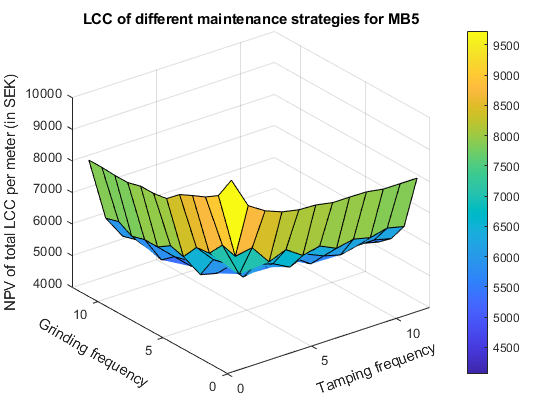

% plot results
plot_figure('LCC_heatmap MB5', simulation_LCC_MB5);

[row_grinding,col_tamping] = find(simulation_LCC_MB5==min(simulation_LCC_MB5(:)))

row_grinding =      9
    10


col_tamping =      9
    10


LCC = min(simulation_LCC_MB5(:))

LCC = 4.0573e+03

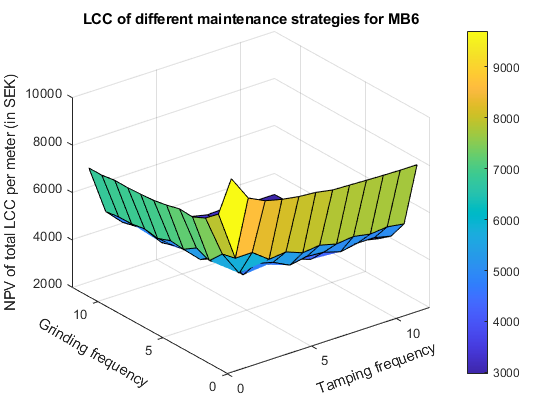

plot_figure('LCC_heatmap MB6', simulation_LCC_MB6);

[row_grinding,col_tamping] = find(simulation_LCC_MB6==min(simulation_LCC_MB6(:)))

row_grinding = 11

col_tamping = 11

LCC = min(simulation_LCC_MB6(:))

LCC = 2.9681e+03